Length: **L**

Distributed load: **w**

Elastic Modulus: **E**

Area moment of inertia: **I**

% Moment function
syms x L w_0 F_A F_B
w(x) = w_0;
eqF = F_A + F_B - int(w(x),x,0,L) == 0;
eqM = L*F_B - int(w(x)*x,x,0,L) == 0;
sol = solve([eqF,eqM],[F_A,F_B]);
FA = sol.F_A

$$FA = \frac{L\,w_{0}}{2}$$

FB = sol.F_B

$$FB = \frac{L\,w_{0}}{2}$$

S(x) = FA - int(w(x),x);
M(x) = int(S(x),x);

$$ans = \frac{L\,w_{0}}{2}-w_{0}\,x$$

$$ans = \frac{w_{0}\,x\,\left(L-x\right)}{2}$$

syms I E v(x)
deq = diff(v,x,2) == M(x)/(E*I);
bc = [v(0) == 0, v(L) == 0];
vsol = dsolve(deq,bc)

$$vsol = -\frac{x\,\left(w_{0}\,L^{3}-2\,w_{0}\,L\,x^{2}+w_{0}\,x^{3}\right)}{24\,\text{E}\,\text{I}}$$

simplify(vsol)

$$ans = -\frac{w_{0}\,x\,\left(L^{3}-2\,L\,x^{2}+x^{3}\right)}{24\,\text{E}\,\text{I}}$$

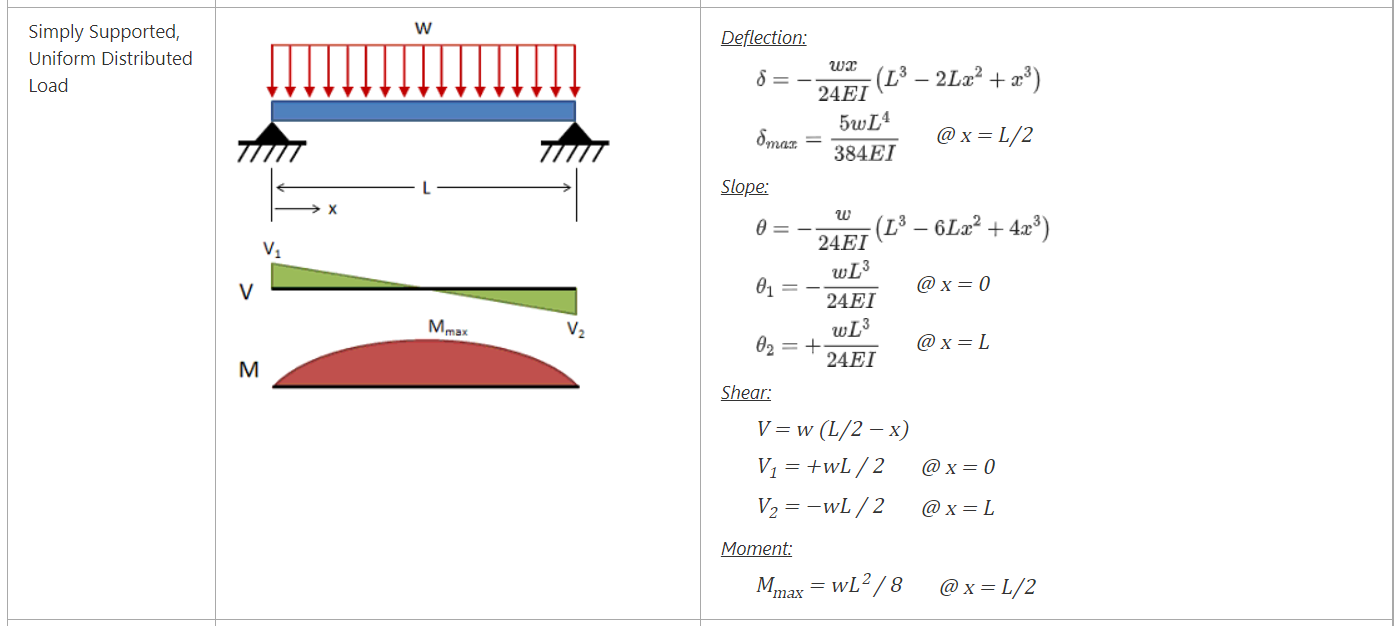

Specific example for comparison to live script solution:


$$$-\frac{x\,{\left(x^3 -10\,x^2 +125\right)}}{4800}$$$


u = symunit

u =   symbolicUnitsCollection with units:

      ampere: [A]
      kelvin: [K]
    kilogram: [kg]
       meter: [m]
        mole: [mol]
      second: [s]
     candela: [cd]

  Show all units.


E = 20*u.GPa;
L = 5*u.m;
w0 = 10*u.kN/u.m;
h = 0.20*u.m;
b = 0.15*u.m;
I = b*h^3/12

$$I = \frac{1}{10000}\,m^{4}$$


v(x) = -w0*x/(24*E*I)*(L^3-2*L*x^2+x^3);
simplify(v(x))

$$ans = -\frac{x\,\left(x^{3}-10\,x^{2}\,m+125\,m^{3}\right)}{4800}\,\frac{1}{m^{3}}$$